clc
clear
close all

N = 6;

File

Robot_type = "ur5e";
dir_name = sprintf("%s/%d", Robot_type, N);
[status, msg, msgID] = mkdir(dir_name);

addpath(genpath("ur5e/"))

a = [0, -0.425, -0.3922, 0, 0, 0];
d = [0.1625, 0, 0, 0.1333, 0.0997, 0.0996];
alpha = [pi/2, 0, 0, pi/2, -pi/2, 0];
m = [3.761, 8.058, 2.846, 1.37, 1.3, 0.365];
theta = [0, 0, 0, 0, 0, 0];

pl1 = [0, -0.02561, 0.00193];
pl2 = [0.2125, 0, 0.11336];
pl3 = [0.15, 0, 0.0265];
pl4 = [0, -0.0018, 0.01634];
pl5 = [0,  0.0018, 0.01634];
pl6 = [0, 0, -0.001159];
CoM = {pl1', pl2', pl3', pl4', pl5', pl6'};

I1 = diag([0.0084, 0.0064, 0.0084]);
I2 = diag([0.0078, 0.21, 0.21]);
I3 = diag([0.0016, 0.0462, 0.0462]);
I4 = diag([0, 0, 0]);
I5 = diag([0, 0, 0]);
I6 = diag([0.0001, 0.0001, 0.0001]);
Inertia = {I1, I2, I3, I4, I5, I6};

% for i = 1:6 % parallel axis theorem
% %     Inertia{i} = Inertia{i} + m(i) * ( ...
% %         CoM{i}' * CoM{i} * eye(3) - ...
% %         CoM{i} * CoM{i}');
%     Inertia{i} = Inertia{i} - ...
%         m(i) * (CoM{i}' * CoM{i} * eye(3) - CoM{i} * CoM{i}');
% end

% %%%%%%%%%%%%%%%%%%%%%%
% % Inertia
% % Rotate
% Icur = M(1:3,1:3)*I(:,:,i)*M(1:3,1:3)';
% % Bring to COM
% %Icur = Icur-((M(1:3,1:3)*p_com(:,i))'*M(1:3,1:3)*p_com(:,i)*eye(3)-M(1:3,1:3)*p_com(:,i)*(M(1:3,1:3)*p_com(:,i))')*mass(i);
% Icur = Icur-(p_com(:,i)'*p_com(:,i)*eye(3)- ...
%     M(1:3,1:3)*p_com(:,i)*(M(1:3,1:3)*p_com(:,i))')*mass(i);
% % Bring to new frame origo
% M = M*[eye(3) p_com(:,i);zeros(1,3) 1];
% %M = simplify(inv(T_ord{i})*T_mod{i}*[eye(3) p_com(:,i);zeros(1,3) 1]);
% Icur = Icur+(M(1:3,4)'*M(1:3,4)*eye(3)-M(1:3,4)*M(1:3,4)')*mass(i);
% Icur = simplify(Icur);
% %%%%%%%%%%%%

dhparams = [a' alpha' d' zeros(6, 1)];
robotUR5e = rigidBodyTree;
robotUR5e.DataFormat = 'column';
robotUR5e.Gravity = [0, 0, -9.82]';

bodies = cell(6,1);
joints = cell(6,1);

visual_names = ["meshes/ur5e/visual/base.stl", ...
    "meshes/ur5e/visual/shoulder.stl", ...
    "meshes/ur5e/visual/upperarm.stl", ...
    "meshes/ur5e/visual/forearm.stl", ...
    "meshes/ur5e/visual/wrist1.stl", ...
    "meshes/ur5e/visual/wrist2.stl", ...
    "meshes/ur5e/visual/wrist3.stl"];

collision_names = ["meshes/ur5e/collision/base.stl", ...
    "meshes/ur5e/collision/shoulder.stl", ...
    "meshes/ur5e/collision/upperarm.stl", ...
    "meshes/ur5e/collision/forearm.stl", ...
    "meshes/ur5e/collision/wrist1.stl", ...
    "meshes/ur5e/collision/wrist2.stl", ...
    "meshes/ur5e/collision/wrist3.stl"];

% mesh_rpyxyz = [0 0 pi 0 0 0;
%                0 0 pi 0 0 0;
%                pi/2 0 -pi/2 0 0 0.138;
%                pi/2 0 -pi/2 0 0 0.007;
%                pi/2 0 0 0 0 -0.127;
%                0 0 0 0 0 -0.0997;
%                pi/2 0 0 0 0 -0.0989];
mesh_rpyxyz = [0 0 pi 0 0 0;
    0 0 pi 0 0 0;
    pi/2 pi -pi/2 -a(2) 0 0.127;
    pi/2 pi -pi/2 -a(3) 0 0;
    0 0 0 0 -d(4) 0;
    0 0 pi/2 0 d(5) -0.007;
    0 0 pi/2 0 0 -d(6) - 7e-4];

for i = 1:N
    bodies{i} = rigidBody(['body' num2str(i)]);
    joints{i} = rigidBodyJoint(['jnt' num2str(i)],"revolute");
    
    
    setFixedTransform(joints{i},dhparams(i,:),"dh");
    
    %     ct = cos(theta(i));
    %     st = sin(theta(i));
    %     calph = cos(alpha(i));
    %     salph = sin(alpha(i));
    %     T = [ct, -st * calph, st * salph, a(i) * ct;
    %          st, ct * calph, -ct * salph, a(i) * st;
    %          0, salph, calph, d(i);
    %          0, 0, 0, 1];
    %
    %     setFixedTransform(joints{i}, T);
    %     Ta = [eye(3), [a(i), 0, 0]'; [0, 0, 0, 1]];
    %     Talpha = [1, 0, 0, 0; 0, cos(alpha(i)), -sin(alpha(i)), 0;...
    %                 0, sin(alpha(i)), cos(alpha(i)), 0; 0, 0, 0, 1];
    %     Td = [eye(3), [0, 0, d(i)]'; [0, 0, 0, 1]];
    %     TL = Td*Ta*Talpha;
    %
    %     setFixedTransform(joints{i}, TL);
    % %     joints{i}.ChildToJointTransform = TL;
    % %     joints{i}.JointToParentTransform = eye(4);
    
    
    bodies{i}.Joint = joints{i};
    
    bodies{i}.Mass = m(i);
    bodies{i}.CenterOfMass = CoM{i}';
    
    %     % % Bring to COM
    %     % %Icur = Icur-((M(1:3,1:3)*p_com(:,i))'*M(1:3,1:3)*p_com(:,i)*eye(3)-M(1:3,1:3)*p_com(:,i)*(M(1:3,1:3)*p_com(:,i))')*mass(i);
    %     % Icur = Icur-(p_com(:,i)'*p_com(:,i)*eye(3)- ...
    %     %     M(1:3,1:3)*p_com(:,i)*(M(1:3,1:3)*p_com(:,i))')*mass(i);
    %     % % Bring to new frame origo
    %     % M = M*[eye(3) p_com(:,i);zeros(1,3) 1];
    %     % %M = simplify(inv(T_ord{i})*T_mod{i}*[eye(3) p_com(:,i);zeros(1,3) 1]);
    %     % Icur = Icur+(M(1:3,4)'*M(1:3,4)*eye(3)-M(1:3,4)*M(1:3,4)')*mass(i);
    %     % Icur = simplify(Icur);
    Inert = Inertia{i} + (CoM{i}' * CoM{i} * eye(3) - ...
        CoM{i} * CoM{i}') * m(i);
    
    bodies{i}.Inertia = [Inert(1, 1), Inert(2, 2), Inert(3, 3), ...
        Inert(2, 3), Inert(1, 3), Inert(1, 2)];
    
    % bodies{i}.Inertia = [diag(Inertia{i}); 0; 0; 0];
    % bodies{i}.Inertia = 0 * bodies{i}.Inertia;
    
    if i == 1 % Add first body to base
        addBody(robotUR5e,bodies{i},"base")
    else % Add current body to previous body by name
        addBody(robotUR5e,bodies{i},bodies{i-1}.Name)
    end
    
    % %     tf_vis = eye(4);
    tf_vis = eul2tform(mesh_rpyxyz(i + 1, 1:3), "ZYX");
    tf_vis(1:3, 4) = mesh_rpyxyz(i + 1, 4:6);
    addVisual(robotUR5e.Bodies{i}, "Mesh", visual_names{i + 1}, tf_vis);
    
    addCollision(robotUR5e.Bodies{i}, "Mesh", visual_names{i + 1}, tf_vis);
end

addVisual(robotUR5e.Bodies{1}.Parent, "Mesh", visual_names{1});
addCollision(robotUR5e.Bodies{1}.Parent, "Mesh", visual_names{1});

% add end effector
bodyEndEffector = rigidBody('end_effector');
bodyEndEffector.Mass = 0;
bodyEndEffector.Inertia = zeros(6, 1);
tform_ee = trvec2tform([0, 0, 0]); % User defined
setFixedTransform(bodyEndEffector.Joint, tform_ee);
addBody(robotUR5e, bodyEndEffector, robotUR5e.Bodies{end}.Name);

showdetails(robotUR5e);

--------------------
Robot: (7 bodies)

 Idx           Body Name              Joint Name              Joint Type           Parent Name(Idx)   Children Name(s)
 ---           ---------              ----------              ----------           ----------------   ----------------
   1               body1                    jnt1                revolute                    base(0)   body2(2)  
   2               body2                    jnt2                revolute                   body1(1)   body3(3)  
   3               body3                    jnt3                revolute                   body2(2)   body4(4)  
   4               body4                    jnt4                revolute                   body3(3)   body5(5)  
   5               body5                    jnt5                revolute                   body4(4)   body6(6)  
   6               body6                    jnt6                revolute                   body5(5)   end_effector(7)  
   7        end_effector        end_e

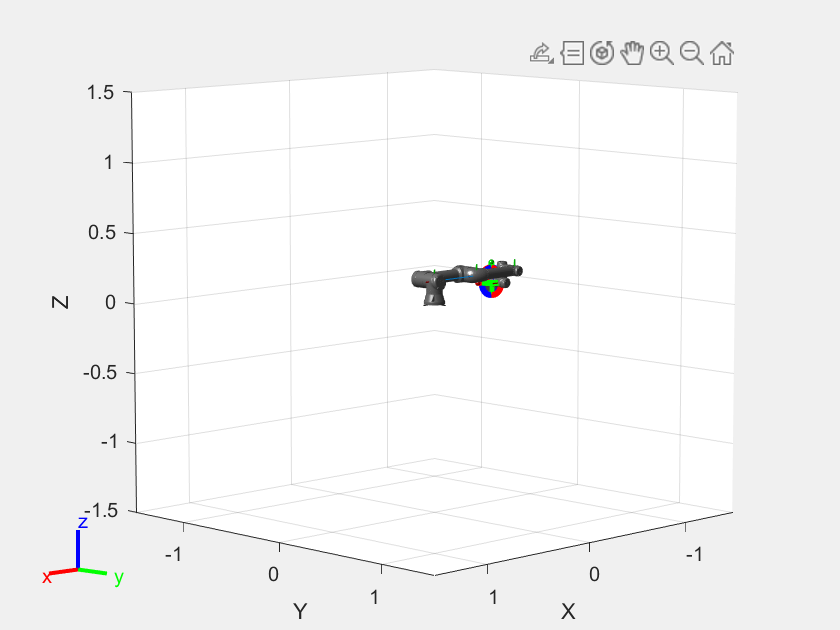


% figure;
% show(robotUR5e, Visuals="on", Collisions="off")
interactiveRigidBodyTree(robotUR5e,MarkerScaleFactor=0.5);

## Export

writeAsFunction(robotUR5e, "UniversalUR5e")

file_name = sprintf("%s/Robot.mat", dir_name);
save(file_name, "robotUR5e");
close all